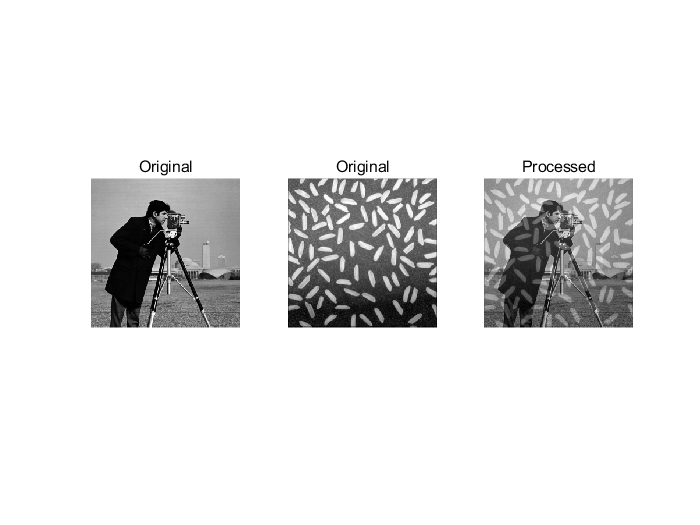

% 两幅图像的加法运算
imgSize = 256;
A = imread('Fig0.tif');
B = imread('Fig2.tif');
% 所有的图像要统一尺寸
A = imresize(A, [imgSize, imgSize]);
B = imresize(B, [imgSize, imgSize]);
C = imadd(A, B, 'uint16');
figure
subplot(1,3,1)
imshow(A, [])
title('Original')
subplot(1,3,2)
imshow(B, [])
title('Original')
subplot(1,3,3)
imshow(C, [])
title('Processed')

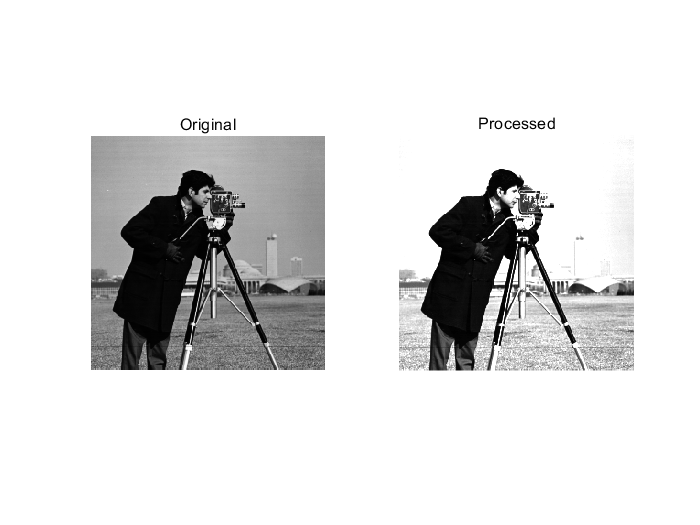

% 图像亮度的加法运算
D = imadd(A, 100);
figure
subplot(1,2,1)
imshow(A, [])
title('Original')
subplot(1,2,2)
imshow(D, [])
title('Processed')

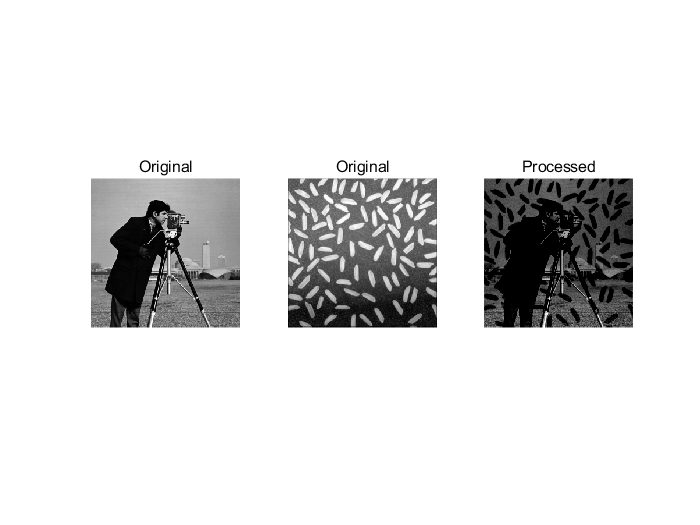

% 两幅图像的减法运算
E = imsubtract(A, B);
figure
subplot(1,3,1)
imshow(A, [])
title('Original')
subplot(1,3,2)
imshow(B, [])
title('Original')
subplot(1,3,3)
imshow(E, [])
title('Processed')

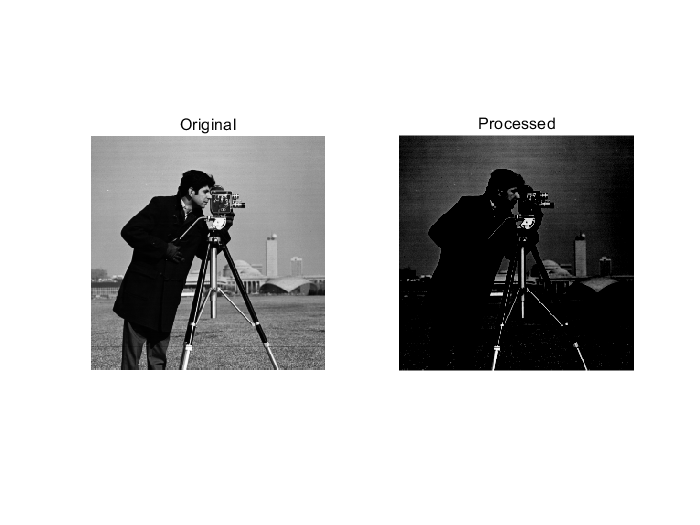

% 两幅图像的减法运算
E = imsubtract(A, 150);
figure
subplot(1,2,1)
imshow(A, [])
title('Original')
subplot(1,2,2)
imshow(E, [])
title('Processed')

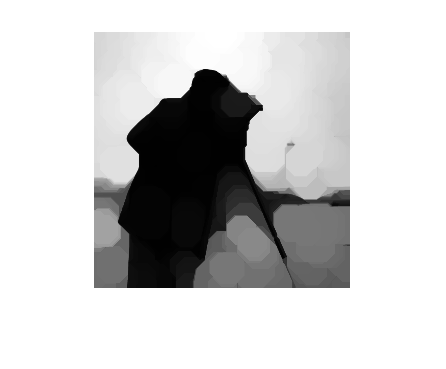

% PS
background = imopen(A,strel('disk',15)); % strel('disk',15)创建半径15的圆盘，类型Structuring element
% 看了一下文档，本质上就是通过SE结构，将图像非背景区域的轮廓标定出来，以得到背景图像
figure
imshow(background, [])

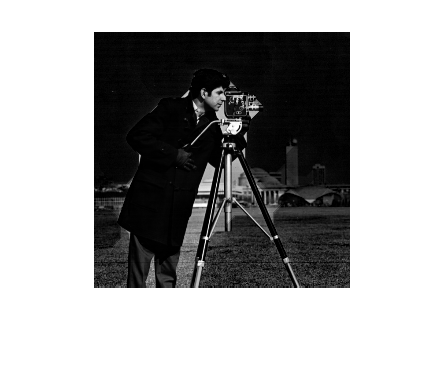

F = imsubtract(A, background);
figure
imshow(F, [])

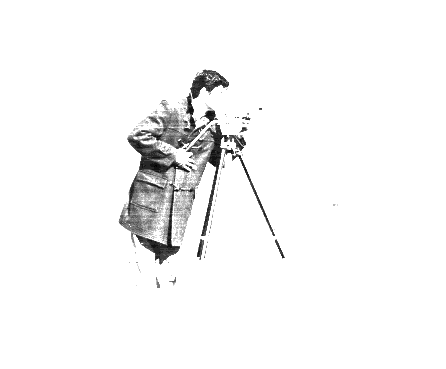

% 两幅图像的乘法运算
G = immultiply(A, A); % 自乘增加对比度
figure
imshow(G, [])

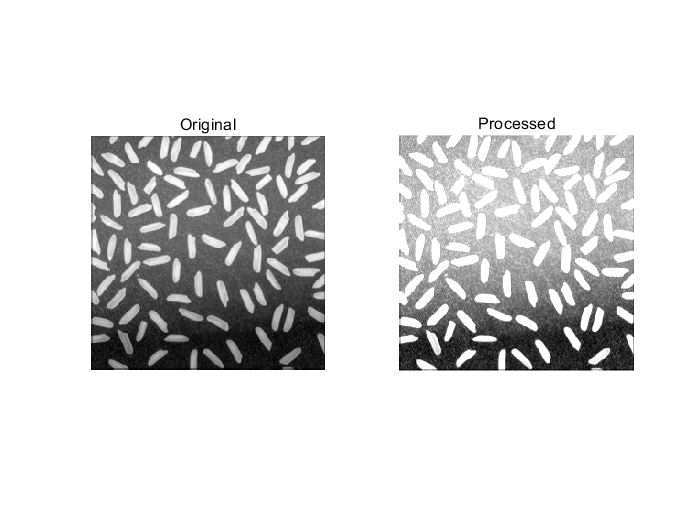

% 图像亮度的乘法运算
H = immultiply(B, 2);
figure
subplot(1,2,1)
imshow(B, [])
title('Original')
subplot(1,2,2)
imshow(H, [])
title('Processed')

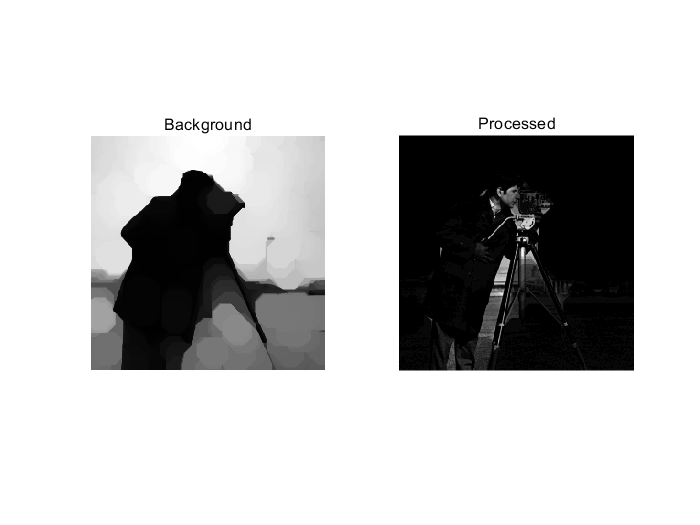

% 两幅图像的除法运算
background = imopen(A,strel('disk',15)); % strel('disk',15)创建半径15的圆盘，类型Structuring element
I = imdivide(A, background);
figure
subplot(1,2,1)
imshow(background, [])
title('Background')
subplot(1,2,2)
imshow(I, [])
title('Processed')

% 图像亮度的除法运算
J = imdivide(B, 0.5);
figure
subplot(1,2,1)
imshow(B, [])
title('Original')
subplot(1,2,2)
imshow(J, [])
title('Processed')

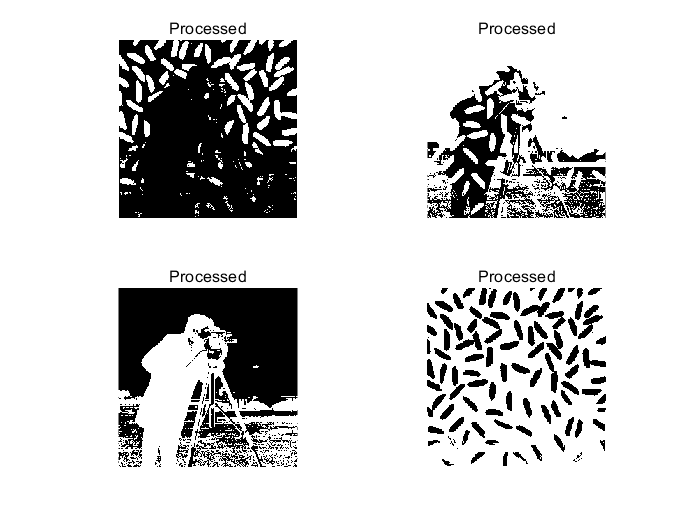

% 图像逻辑运算
A = im2bw(A, 0.5);
B = im2bw(B, 0.5);
K = A&B;
L = A|B;
M = ~A;
N = ~B;
figure
subplot(2,2,1)
imshow(K, [])
title('Processed')
subplot(2,2,2)
imshow(L, [])
title('Processed')
subplot(2,2,3)
imshow(M, [])
title('Processed')
subplot(2,2,4)
imshow(N, [])
title('Processed')

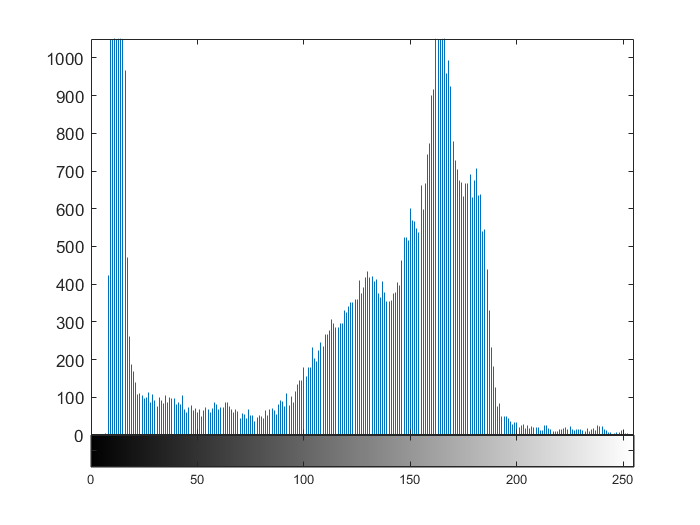

figure
A = imread('Fig0.tif');
figure
hist = imhist(A, 25);
imhist(A)

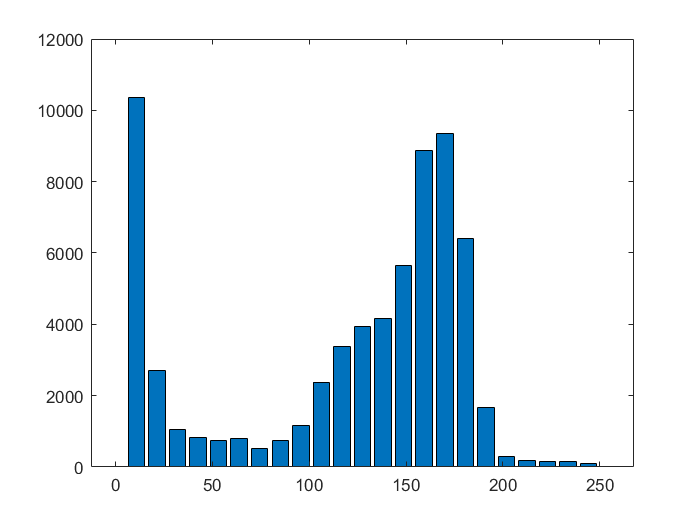

horz = linspace(0,255,25);
figure
bar(horz, hist)

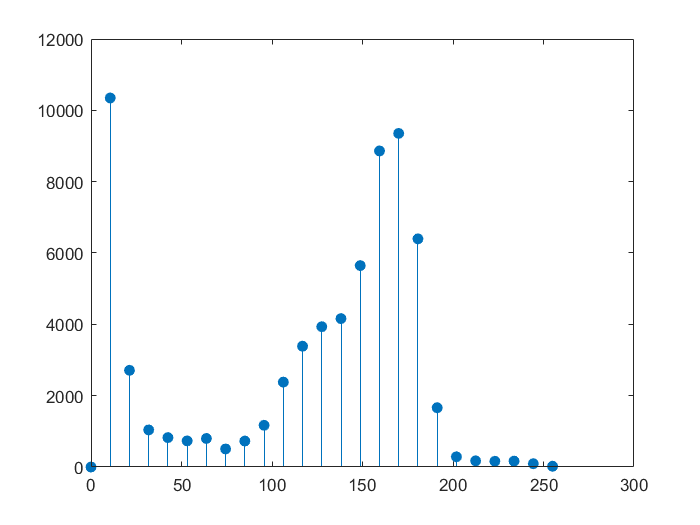

stem(horz, hist, 'filled')
xlim([0 300])
ylim([0 12000])